# Analytical design of two degree-of-freedom decoupling control scheme for two-by-two systems with integrator(s)

#### Comments: 

- RHP zeros: [https://electronics.stackexchange.com/questions/423995/effect-of-rhp-zeros-on-stability](https://electronics.stackexchange.com/questions/423995/effect-of-rhp-zeros-on-stability)

- Pole and zero locations: [https://www.mathworks.com/help/control/ug/pole-and-zero-locations.html](https://www.mathworks.com/help/control/ug/pole-and-zero-locations.html)

- Estabilidade: [http://www.ece.ufrgs.br/~jmgomes/pid/Apostila/apostila/node11.html](http://www.ece.ufrgs.br/~jmgomes/pid/Apostila/apostila/node11.html)

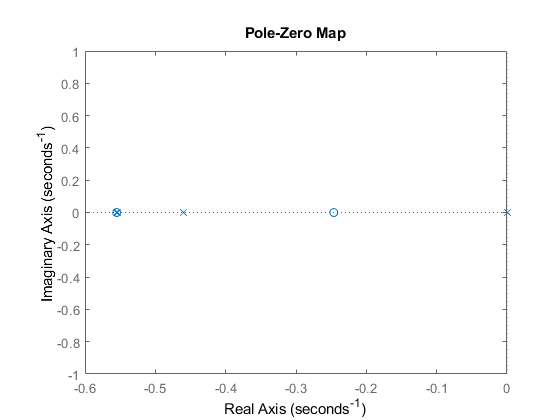

close all
clearvars

s = tf('s', 'TimeUnit', 'seconds');
G(1,1) = (5/s);
Ga(1,1) = exp(-0.2*s);

G(1,2) = (-11.64/(1.807*s + 1));
Ga(1,2) = exp(-0.4*s);

G(2,1) = (4.689/(2.174*s+1));
Ga(2,1) = exp(-0.2*s);

G(2,2) = (5.80/(1.801*s + 1));
Ga(2,2) = exp(-0.4*s);

G;                       % Modelo sem atraso
Gdelay = Ga;             % Atrasos presentes no modelo
Gmodel = G.*Gdelay;      % Função de transferência G do modelo c/ atrasos


% Não tem RHP (SPD - polos semi plano direito): 
zeros = tzero(pade(Gmodel));
polos = pole(Gmodel);
pzplot(Gmodel);


% adjG = adj(Gmodel)